load ARTEMIS 
driving_cycle=ARTEMIS;
speed=ARTEMIS(1,:);

i=1;
j=1;
while i<length(speed)
    if speed(i)~=0 && rand<=0.3
        while(rand<0.8)
            speed(i)=max(speed(i)-0.8*j,0);
            i=i+1;
            j=j+1;
        end
        j=1;
    end
    i=i+1;
end




acceleration=[speed(1:end-1)-speed(2:end),0];

for i=1:length(speed)
    % Determina la marcia in base alla velocità
    if speed(i) <= 20/3.6
        gearnumber(i) = 1;
    elseif speed(i) <= 40/3.6
        gearnumber(i) = 2;
    elseif speed(i) <= 60/3.6
        gearnumber(i) = 3;
    elseif speed(i) <= 90/3.6
        gearnumber(i) = 4;
    else
        gearnumber(i) = 5;
    end
    
    % Aggiusta la marcia in base all'acceleration_vector(i)
    if acceleration(i) > 2.0 && gearnumber(i) > 1
        gearnumber(i) = max(1, gearnumber(i) - 1);  % Scendi di una marcia se l'acceleration_vector(i) è alta
    elseif acceleration(i) < 0.5 && gearnumber(i) > 1
        gearnumber(i) = min(6, gearnumber(i) + 1);  % Sali di una marcia se l'acceleration_vector(i) è molto bassa
    end
end

sum(ARTEMIS(1,:))-sum(speed)

ans = 1.1364e+03

sum(ARTEMIS(1,:))

ans = 4.8698e+03

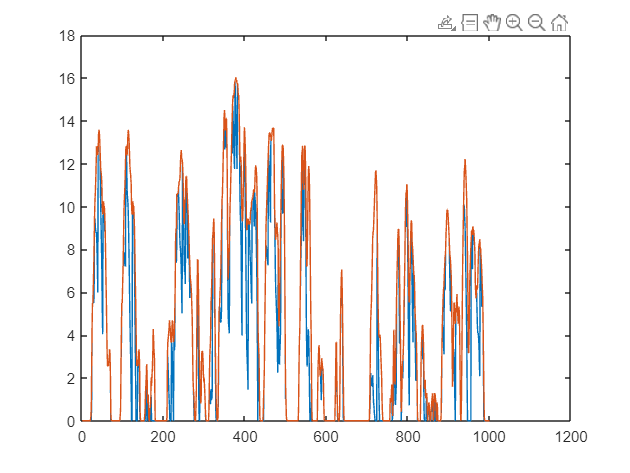

plot(speed)
hold on
plot(ARTEMIS(1,:))
hold off

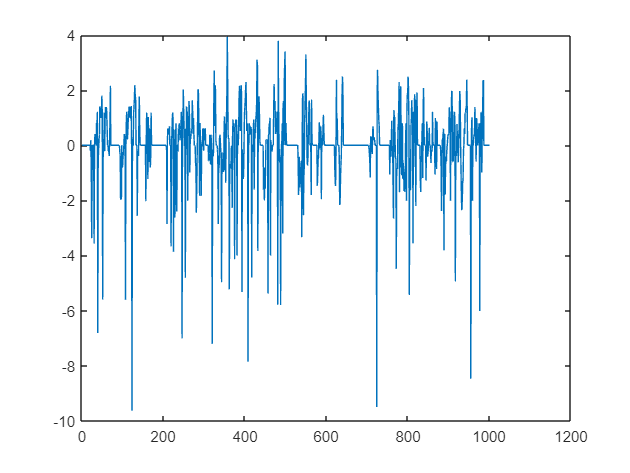

plot(acceleration)